# PCA 분석 및 회귀

참조논문 : 

건전성 지표 기반 주성분분석(PCA)을 적용한 고용량 배터리

팩의 열화 인자 추출 방법 및 SOH 진단 기법 연구

이평연1, 권상욱1, 강덕훈1, 한승윤1, 김종훈✝

SOH Estimation and Feature Extraction using Principal Component Analysis

based on Health Indicator for High Energy Battery Pack

Pyeong-Yeon Lee1, Sanguk Kwon1, Deokhun Kang1, Seungyun Han1, and Jonghoon Kim✝

C:\nobackup\project-matlab\battery\__doc_battery\ref\SOH Estimation and Feature Extraction using Principal Component Analysis based on Health Indicator for High Energy Battery Pack.pdf

## **Cycle 에 따른 Capacity 그래프**  

그림 3(a)은 식 (3)에 의해 만충부터 만방까지의 방전

전류 누적을 통해 산출된 방전 용량을 나타내고, 초기

방전 용량 대비 약 3%의 용량 감소가 발생하였음을 확

인하였다

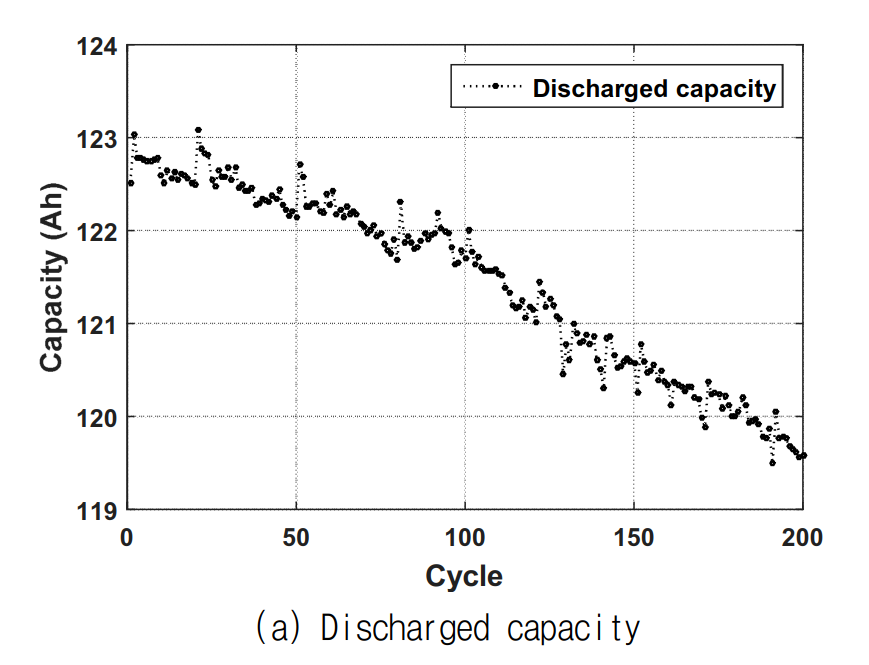

load B0005.mat
load B0006.mat
load B0007.mat
load B0018.mat

BAT1 =B0005;
BAT2 =B0006;
BAT3 =B0007; 

cap5 = extract_discharge(BAT1);





### Comment

Ctrl + R / T %{

### Test function


% A set of four Li-ion batteries (# 5, 6, 7 and 18) were run through 3 different operational profiles (charge, discharge and impedance) at room temperature. Charging was carried out in a constant current (CC) mode at 1.5A until the battery voltage reached 4.2V and then continued in a constant voltage (CV) mode until the charge current dropped to 20mA. Discharge was carried out at a constant current (CC) level of 2A until the battery voltage fell to 2.7V, 2.5V, 2.2V and 2.5V for batteries 5 6 7 and 18 respectively. Impedance measurement was carried out through an electrochemical impedance spectroscopy (EIS) frequency sweep from 0.1Hz to 5kHz. Repeated charge and discharge cycles result in accelerated aging of the batteries while impedance measurements provide insight into the internal battery parameters that change as aging progresses. The experiments were stopped when the batteries reached end-of-life (EOL) criteria, which was a 30% fade in rated capacity (from 2Ahr to 1.4Ahr). This dataset can be used for the prediction of both remaining charge (for a given discharge cycle) and remaining useful life (RUL).

[cap,maxTemp,maxTimeDelta,abnormal,ohm,re_c,re_d] = extract_feature(BAT1);
corVector = [cap'  maxTemp' maxTimeDelta' ohm' re_c' re_d'];
corVector2 = [cap'  maxTimeDelta'];

RegVector = [cap'  maxTemp' maxTimeDelta' ohm' ];
RegVector2 = [cap' maxTimeDelta' ];

% 주성분 분석은 독립변수로만
X_vars =  [maxTemp' maxTimeDelta' ohm' cap' ];
%X_vars =   maxTimeDelta';
Y_vars = cap';

corVectorPca = [ maxTemp' maxTimeDelta' ohm' ];

nCycle = 169; %60
nX = size(X_vars,2); % 401
%nX = 1;


[dummy,h] = sort(Y_vars);
oldorder = get(gcf,'DefaultAxesColorOrder');
set(gcf,'DefaultAxesColorOrder',jet(60));

% https://kr.mathworks.com/matlabcentral/answers/329299-how-to-normalize-vector-to-unit-length
% do normalize to plot
R = X_vars; 
Rmax = repmat(max(R), size(R,1), 1);
Rmin = repmat(min(R), size(R,1), 1);
R_unity = (R - Rmin)./(Rmax - Rmin);
    
plot3(repmat(1:nCycle,nX,1)',repmat(1:nX,nCycle,1),R_unity );
%plot3(repmat(1:nCycle,nX,1)',repmat(1:nCycle,nX,1),X_vars );
% ,repmat(Y_vars(h),1,nX) 
%plot3(repmat(1:401,60,1)',repmat(octane(h),1,401)',NIR(h,:)');

set(gcf,'DefaultAxesColorOrder',oldorder);
xlabel('Cycle'); ylabel('X index');  zlabel('X: Variables'); axis('tight');
grid on

tbl = array2table(RegVector,...
    'VariableNames',{'cap','maxTemp','maxTimeDelta','ohm'});
tbl2 = array2table(RegVector2,...
    'VariableNames',{'cap','maxTemp'})

% https://kr.mathworks.com/help/stats/fitlm.html

%mdl = fitlm(T,cap')
lm = fitlm(tbl,'cap~maxTemp+maxTimeDelta+ohm')
modelspec = 'cap~maxTimeDelta';
mdl = fitlm(tbl,modelspec )

lm.Coefficients
mdl.Coefficients
% https://kr.mathworks.com/help/stats/linearmodel.plot.html
plot(lm)

plot(mdl)
plotResiduals(mdl)

outlier = mdl.Residuals.Raw > 0.2;
find(outlier)
mdl = fitlm(tbl,modelspec,...
    'Exclude',find(outlier));

mdl.ObservationInfo(84,:)
mdl1 = step(mdl,'NSteps',10)
plotResiduals(mdl1)


% y = mdl.Coefficients
cap5hat = 4.09585292607480 - 0.0952839654207921*maxTemp +  0.000196894463615833*maxTimeDelta - 82.6228614134608*ohm;
cap5hat1 = table2array(lm.Coefficients(1,1)) ...
    + table2array(lm.Coefficients(2,1))*maxTemp ...
    + table2array(lm.Coefficients(3,1))*maxTimeDelta ...
    + table2array(lm.Coefficients(4,1))*ohm ;

figure
[R,PValue] = corrplot(corVector2,'type','Pearson','testR','on','varNames',{'Cap','maxTimeDelta'})

figure
plot(cap5), hold on, plot(cap5hat')
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5 real', 'Battery #5 esti', 'Failure Threshold')
title('Capacity Degradations in Cycle - real and esti')


4.09585292607480	0.227155110205607	18.0310842330048	7.46164930980593e-41

-0.0952839654207921	0.00835224901979087	-11.4081806223706	1.35336543592271e-22

0.000196894463615833	1.30246355211347e-05	15.1170804969044	5.83185913112480e-33

-82.6228614134608	13.4185717416945	-6.15735139357142	5.43873148600241e-09


lm1 = fitlm(tbl,'linear')
lm2 = fitlm(tbl,'interactions')
lm3 = fitlm(tbl,'purequadratic')
lm4 = fitlm(tbl,'quadratic')
%lm5 = fitlm(tbl,'polyi13')




testend =1;


[](https://m.blog.naver.com/cjh226/220841229204)

## 테스트


%corVectorPca = A;


%% 정규화 적용전
covx = cov(corVectorPca)
 %% 정규화 적용후
SD = sqrt(diag(corVectorPca)) 
R = covx ./ (SD * SD')
[coeff, latent, explained] = pcacov(R)

%% 주성분으로의 사영(projection)한 결과 출력
result_covx = corVectorPca * coeff
result_R = corVectorPca * coeff
 
 
 
figure
plot(cap), hold on, 
yyaxis right
plot(maxTimeDelta) %, plot(maxTimeDelta)
%plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle
legend('Capacity', 'Time to Max Temp')%, 'Time to Max Temp')
title('Capacity Degradations and Time to Max Temp in Charge Cycle')




그림 3(b)는 내부 저항을 나타내고, 만충의 개

방 회로 전압(Open circuit voltage)에서 방전 전류가 인

가되었을 때, 발생하는 전압 차이를 이용하여 옴의 법칙

(Ohm`s law)을 통해 산출한 저항을 의미한다.

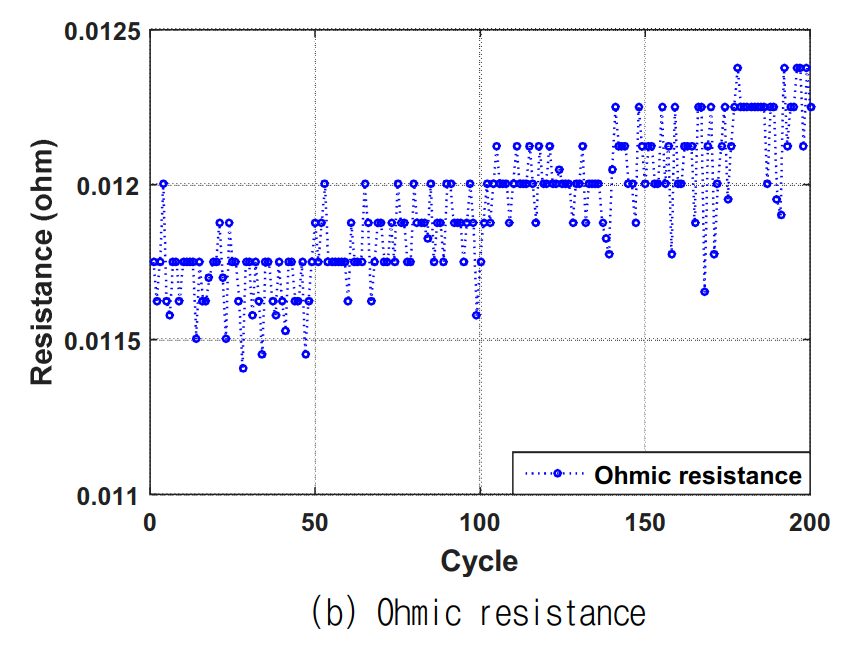

 3(c)는 1

주기에서의 최대 온도를 나타내며, 초기 최대 온도 대비

약 2.5%의 증가를 확인하였다

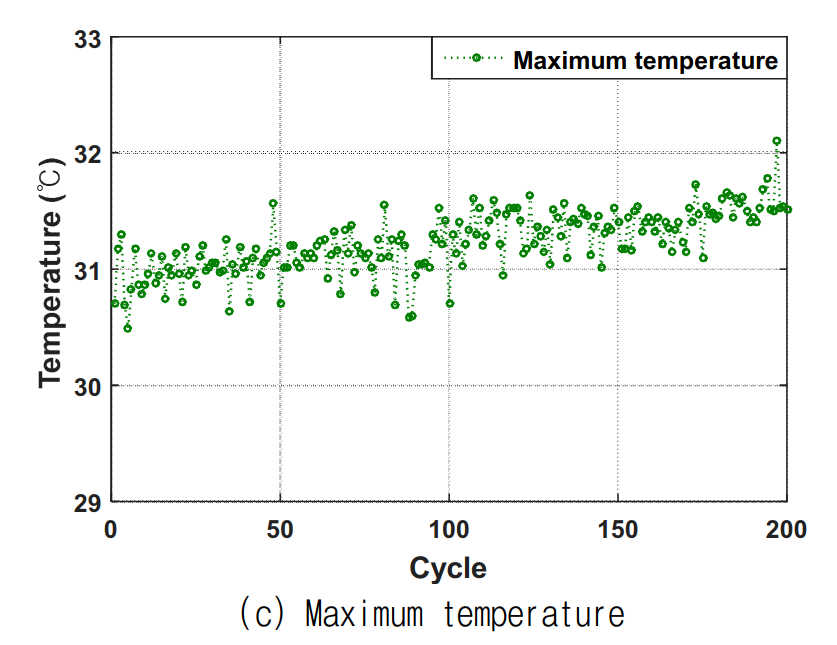

그림 3(d)는 셀 간 온도 편차를 나타낸다. 충·방전이

진행될수록 공조기가 있더라도 배터리 팩 내부 온도 불

균형이 발생하게 되며, 온도의 불균형으로 인해 배터리

팩 내부 단일 셀의 노화 정도가 달라지게 되어 급격한

성능 저하가 발생할 수 있다.

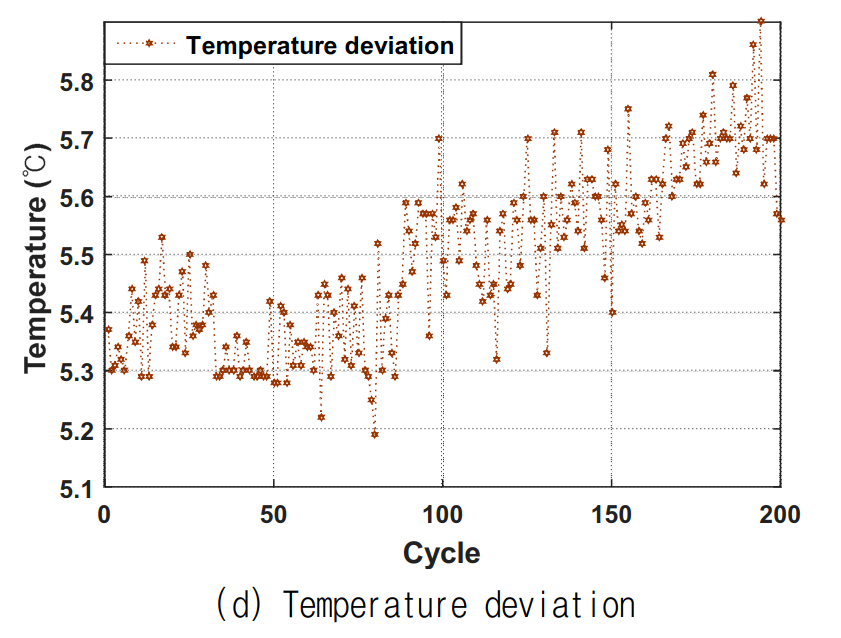

박종용 : NASA 데이타는 셀 하나로 테스트 하였으므로 동일한 그림을 확인할 수 없다.

그림 3(e)와 그림 3(f)는

최소 전압과 셀 간 전압 편차를 나타내며, 셀 간 전압

편차는 최대 셀과 최소 셀 전압의 차이로 계산된다. 초

기최소전압과셀 간전압 편차의차이는4.2%, 약 3배

가 된다. 배터리 팩의 충방전에 따라 배터리 팩 내부 셀

간 전압 불균형이 가속화되며, 이로 인해 과충전 및 과

방전이 발생할 수 있다. 

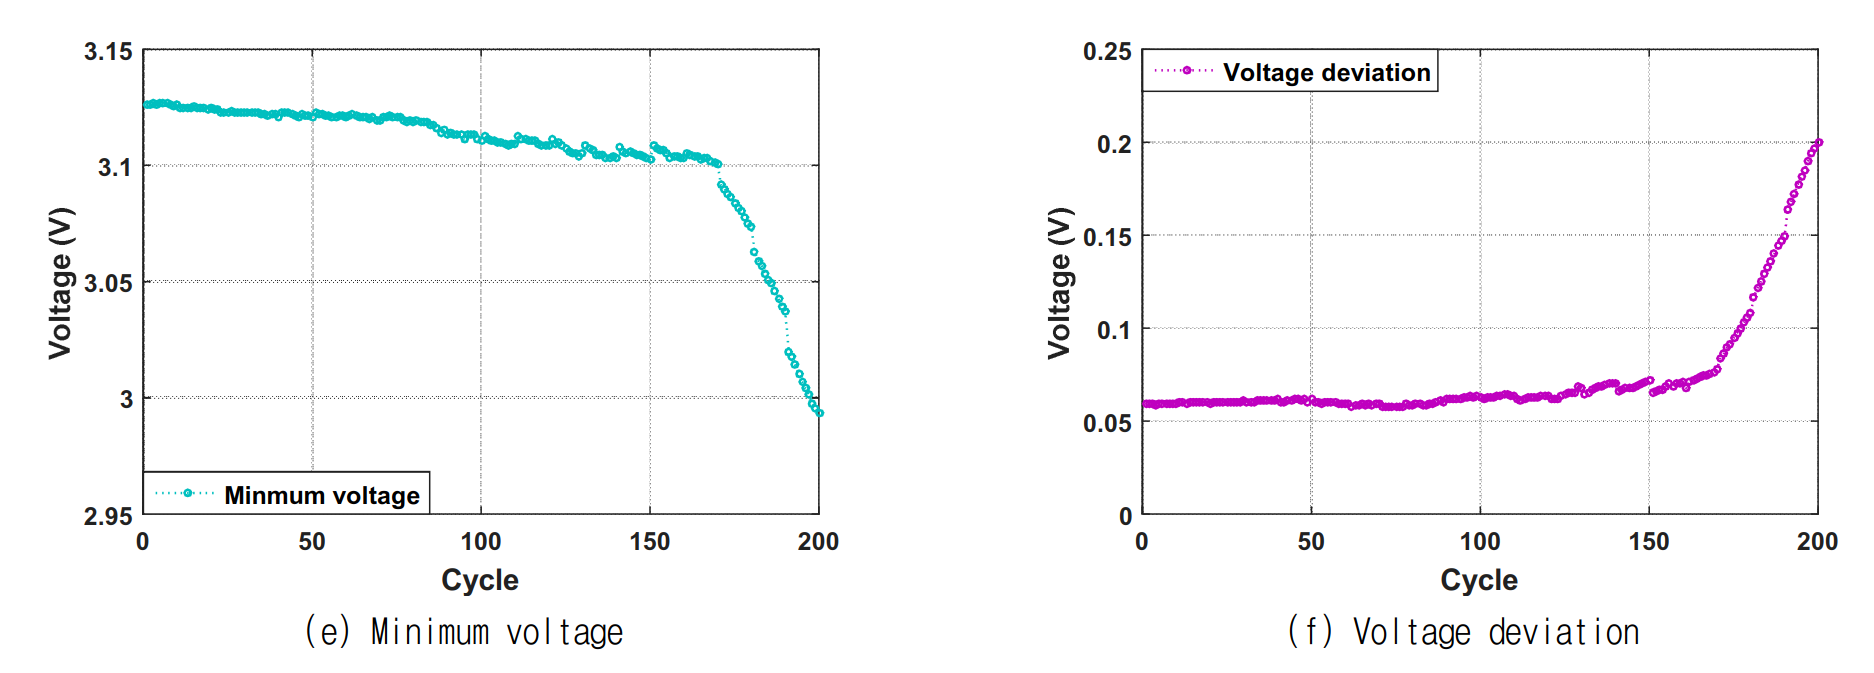



cap5 = extract_discharge(BAT1);
cap6 = extract_discharge(BAT2);
cap7 = extract_discharge(BAT3);
figure
plot(cap5), hold on, plot(cap6), plot(cap7)
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5', 'Battery #6', 'Battery #7', 'Failure Threshold')
title('Capacity Degradations in Cycle')

